close("all"); clear; clc;

x = [-9,-4,-1,7];
y = [5,2,-2,9];
n = numel(x) - 1;

t = sym('t');
l = diag(y)*lagpol(x,t)

$$l = \left[\begin{array}{c} -0.0078\,t^{3}+0.0156\,t^{2}+0.2422\,t+0.2188\\ 0.0121\,t^{3}+0.0364\,t^{2}-0.7394\,t-0.7636\\ 0.0104\,t^{3}+0.0625\,t^{2}-0.5729\,t-2.6250\\ 0.0064\,t^{3}+0.0895\,t^{2}+0.3132\,t+0.2301 \end{array}\right]$$

fl = matlabFunction(l);
ns = 100;
t = linspace(x(1),x(end),ns);
ft = [fl(t);sum(fl(t),1)];

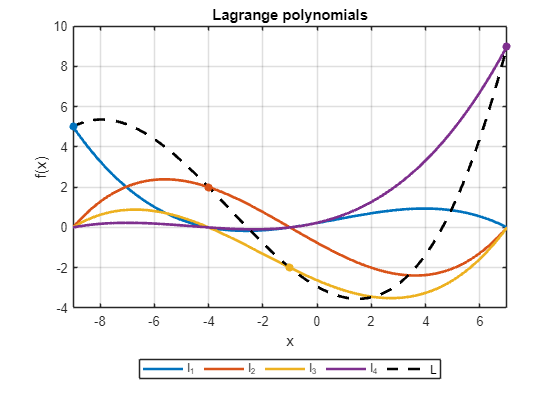

fig = figure();
axe = axes(fig);
for i = 1:n + 2
    hold("on");
    plot(axe,t,ft(i,:),"LineWidth",2);
    hold("off");
end
l = flipud(axe.Children);
l(end).Color = [0,0,0];
l(end).LineStyle = "--";
for i = 1:n + 1
    hold("on");
    scatter(axe,x(i),y(i),"filled","CData",l(i).Color);
    hold("off");
end
leg_names = arrayfun(@(i)"l_" + i,1:n + 1,"UniformOutput",false);
leg_names = [leg_names,{"L"},cellstr(repmat("",[1,n + 1]))];
legend(leg_names{:}, ...
    "Location","SouthOutside", ...
    "Orientation","Horizontal")
box("on");
grid("on");
xlim([x(1),x(end)]);
title(axe,"Lagrange polynomials");
xlabel(axe,"x");
ylabel(axe,"f(x)");